# Examples for using the `bisection_method` function.

Copyright © 2021 Tamas Kis

## Example #1: Root of a simple function.

*Find the root of *$f\left(x\right)=x^2 -1$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

Defining $f\left(x\right)$,

f = @(x) x^2-1;

We want a root in the interval $\left\lbrack 0,\infty \right)$. Therefore, we use the initial guess $\left\lbrack a,b\right\rbrack =\left\lbrack 0,9999999\right\rbrack$. Finding this root using the bisection method,

root = bisection_method(f,0,9999999)

root = 1.0000

## Example #2: Plot of intermediate root estimates.

*In example #1, we found the positive root of *$f\left(x\right)=x^2 -1$* using the bisection method. Now, produce a plot of the intermediate root estimates obtained by the bisection method before it returned the converged root.*

First, we define $f\left(x\right)$ in MATLAB like before.

f = @(x) x^2-1;

To obtain the intermediate root estimates, we simply need to call the `bisection_method` function with the optional input `'all'`.

intermediate_roots = bisection_method(f,0,9999999,[],[],'all');

Plotting the intermediate root estimates,

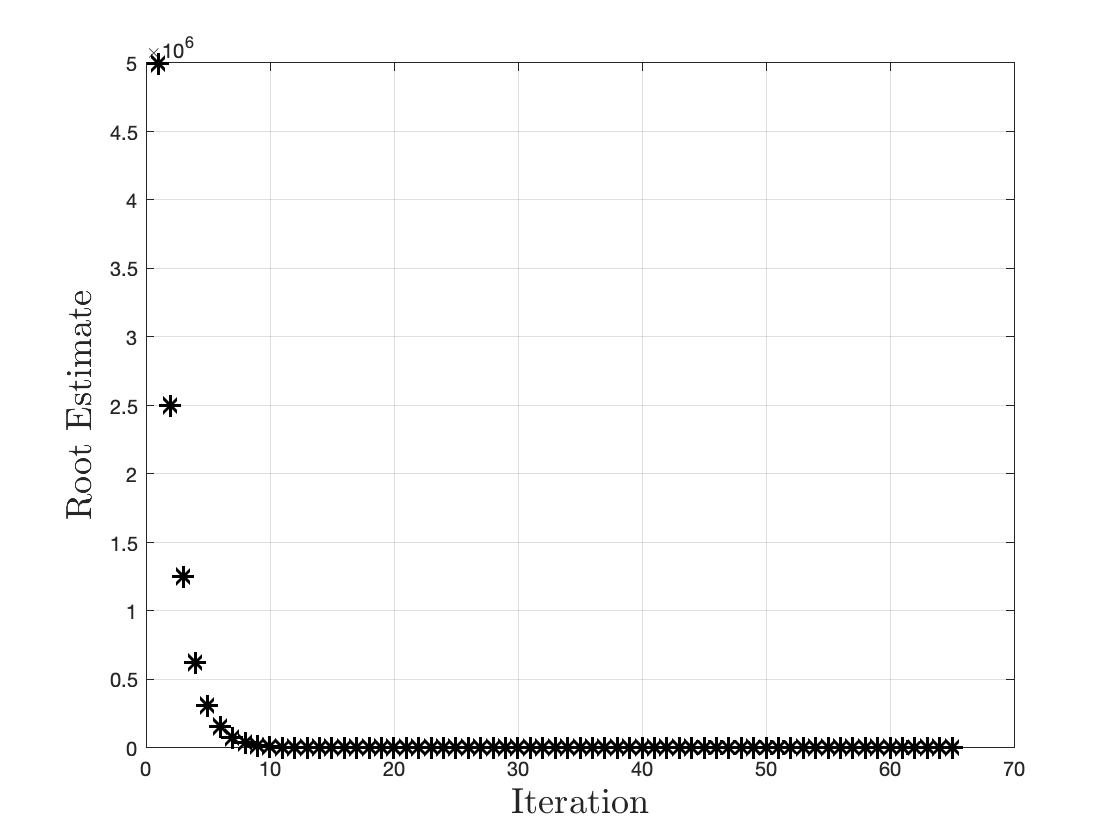

figure;
plot(intermediate_roots,'k*','markersize',9,'linewidth',1.5);
grid on;
xlabel('Iteration','interpreter','latex','fontsize',18);
ylabel('Root Estimate','interpreter','latex','fontsize',18);

We can also extract the converged root from `intermediate_roots`.

root = intermediate_roots(end)

root = 1.0000

## Example #3: Root of a more complicated function.

*Find all the roots of *$g\left(x\right)$ in the interval $\left\lbrack 0,20\right\rbrack$ where $g\left(x\right)$ is defined using the following calculation procedure:

- 
$$c=5x^2$$


- 
$$d=\sin \left(\frac{c}{500}\right)$$


- 
$$e=\cosh \left(d\right)$$


- 
$$g=5e^2 +27e-40$$


First, we need to define $g\left(x\right)$. We define $g\left(x\right)$ as the MATLAB function $\texttt{gx}$ at the bottom of this page under "gx Function for Example #3". To define $g\left(x\right)$ as an anonymous function, we assign it a function handle:

g = @(x) gx(x);

Due to the complexity of $g\left(x\right)$, we have no idea where its root(s) is/are. Therefore, let's first plot $g\left(x\right)$ on $\left\lbrack 0,20\right\rbrack$ (i.e. the interval we want to find the root(s) in).

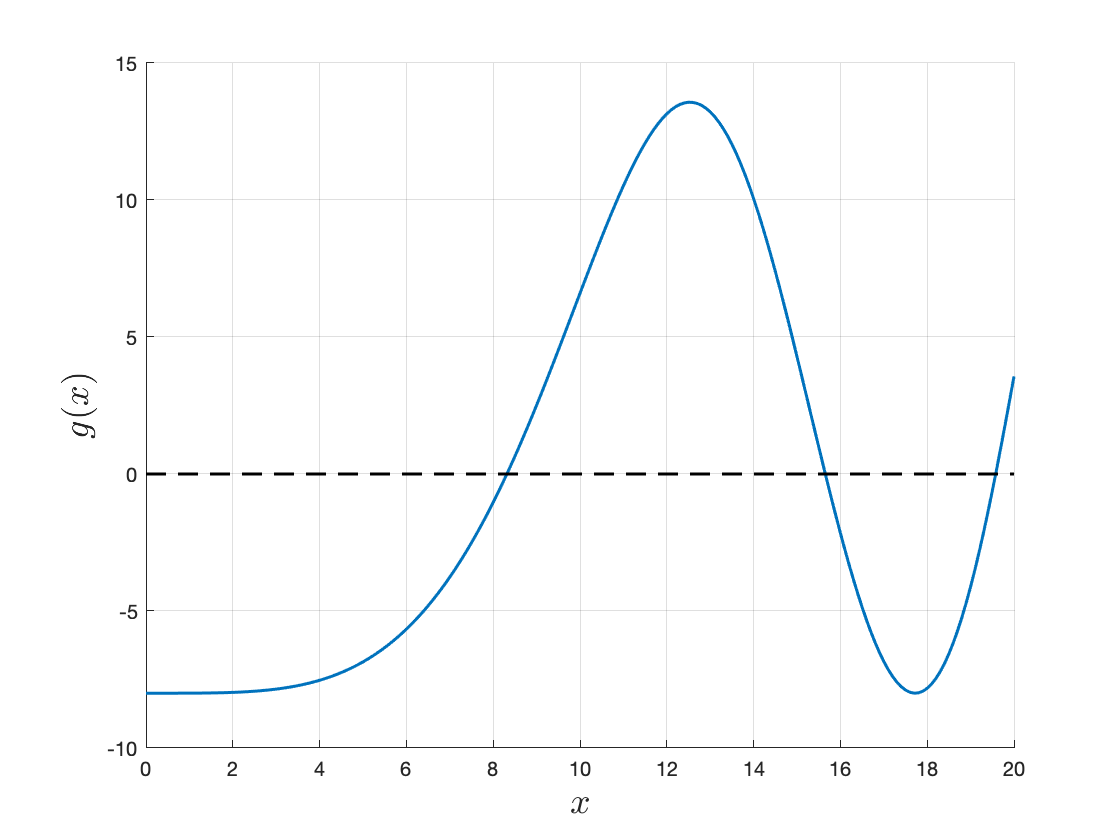

% interval definition
x = 0:0.1:20;

% evaluates g(x) over interval
g_evaluated = g(x);

% plot of g(x) over the interval [-20,20]
figure;
hold on;
plot(x,g_evaluated,'linewidth',1.5);
plot(x,zeros(size(x)),'k--','linewidth',1.5);
hold off;
grid on;
xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$g(x)$','interpreter','latex','fontsize',18);

Visually, we can easily identify the following intervals that contain a root:


$$\left\lbrack 8,9\right\rbrack$$



$$\left\lbrack 15,16\right\rbrack$$



$$\left\lbrack 19,20\right\rbrack$$


Solving for the corresponding roots with the bisection method,

root1 = bisection_method(g,8,9)

root1 = 8.3149

root2 = bisection_method(g,15,16)

root2 = 15.6532

root3 = bisection_method(g,19,20)

root3 = 19.5780

## gx Function for Example #3

function g = gx(x)
    c = 5*x.^2;
    d = sin(c/500);
    e = cosh(d);
    g = 5*e.^2+27*e-40;
end